clear all % 2130-2140 0915-
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


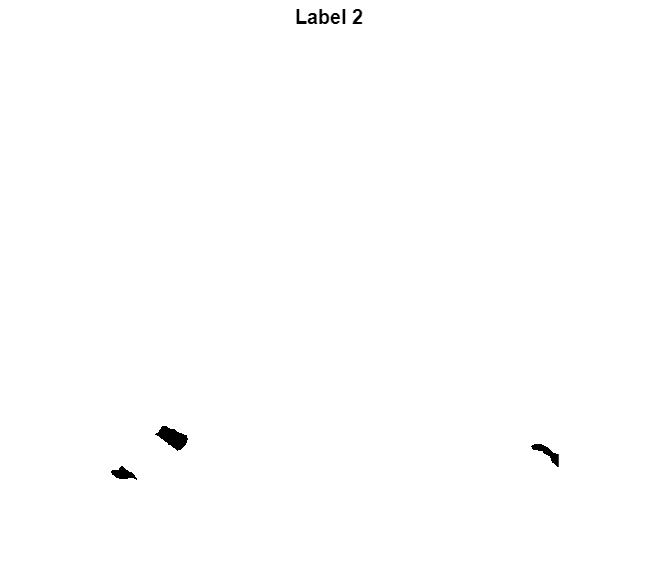


% Locate red pixels edges of landslides
img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);
img_2_hsv = rgb2hsv(img_2);

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH
H_2 = img_2_hsv(:,:,1); % Hue CH
S_2 = img_2_hsv(:,:,2); % Saturation CH
V_2 = img_2_hsv(:,:,3); % Value CH

figure;
imshow(label_2);
title('Label 2');

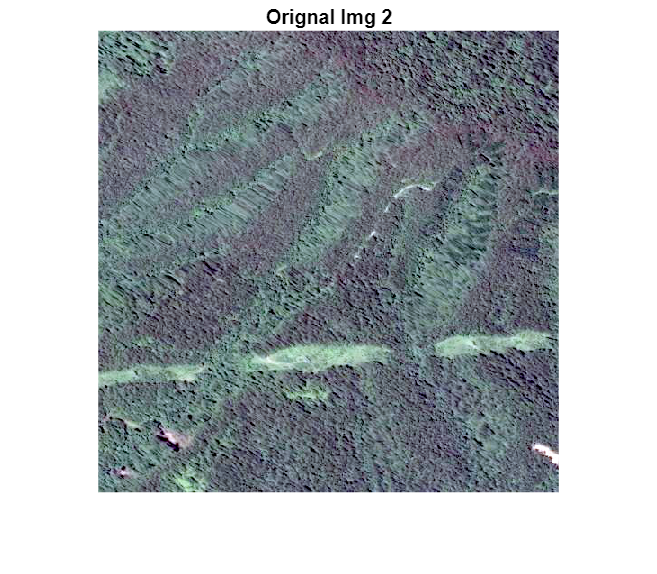

figure;
imshow(img_2);
title('Orignal Img 2');

figure;

% Isolate a section that inlcudes a landlside, analy,se the histogram,
% alter it such that the landlise edge becomes more blocky

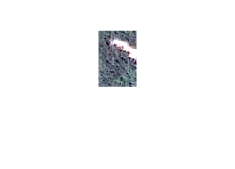

img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);
img_2_hsv = rgb2hsv(img_2);

% Localise landlside
img_2_local = img_2(450:end,470:end,:);
figure;
imshow(img_2_local);

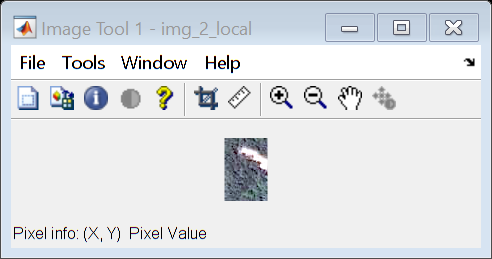

imtool(img_2_local);

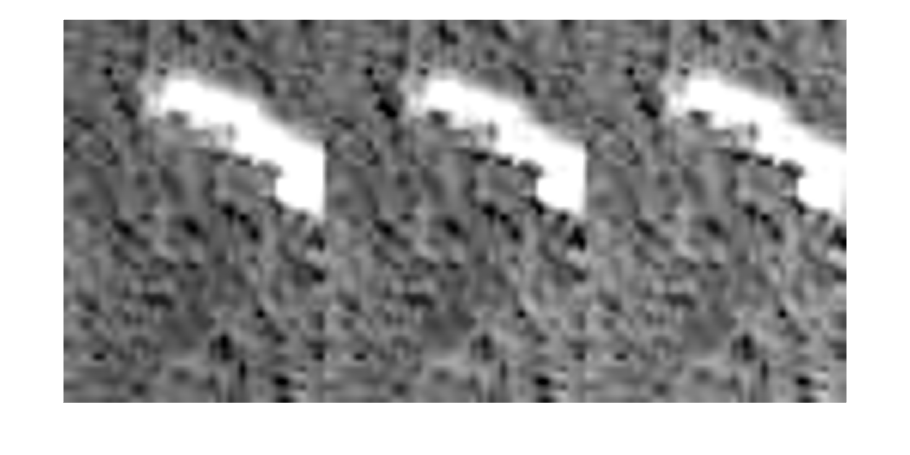

figure;
montage([img_2_local(:,:,1) img_2_local(:,:,2) img_2_local(:,:,3)])

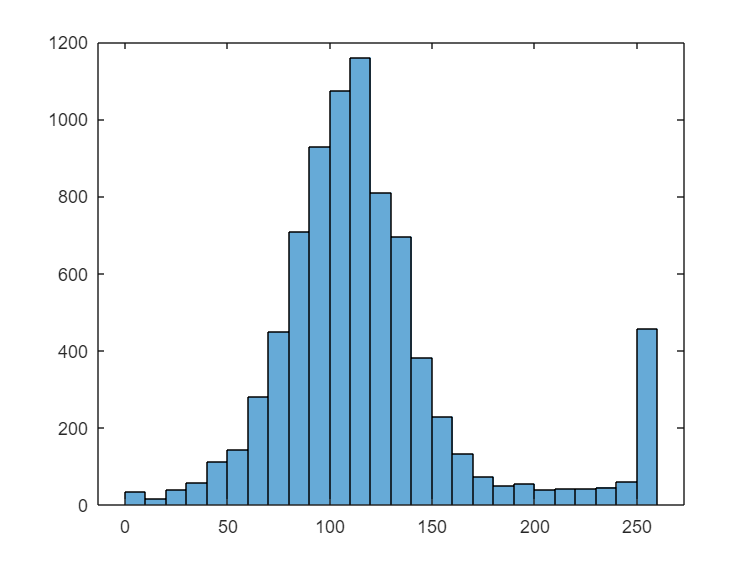


figure;
histogram(img_2_local);

%imtool(img_2_hsv);
% Localise landlside
img_2_hsv_local = img_2_hsv(450:end,470:end,:);
temp = img_2_hsv_local(:,:,3);

[x_b, y_b] = find(img_2_hsv_local(:,:,3)==1)

x_b =     14
    12
    13
    14
    11
    12
    13
    14
    11
    12


y_b =     17
    18
    18
    18
    19
    19
    19
    19
    20
    20


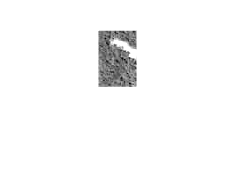

mask_blue = zeros(size(img_2_hsv_local,1),size(img_2_hsv_local,2));
for i=1:x_b
    mask_blue(x_b(i),y_b(i)) = 1;
end
figure;
imshow(img_2_hsv_local(:,:,3));

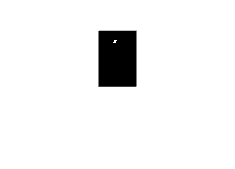

figure;
imshow(mask_blue);


figure;
imshow(temp);

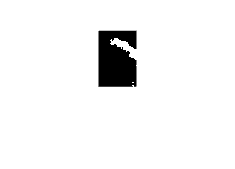

temp(temp>0.7) = 1;
temp(temp<=0.7) = 0;
figure;
imshow(temp);

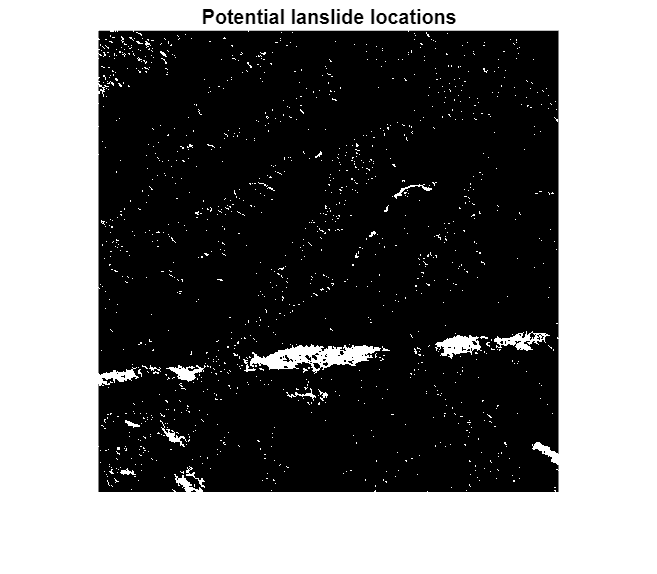

% Select image
img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);

% Transform into HSV format
img_2_hsv = rgb2hsv(img_2);

% Create blue mask
blue_mask = img_2_hsv(:,:,3);
blue_mask(blue_mask>0.7) = 1;
blue_mask(blue_mask<=0.7) = 0;

figure;
imshow(blue_mask);
title('Potential lanslide locations');

clear all % IDENTIFY PATCHES
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";


% Select image
img_2 = double(imread(img_directory + 'Hokkaido0002.tif'));
label_2 = double(imread(label_directory + 'Hokkaido0002.tif'));

% Transform into HSV format
img_2_hsv = rgb2hsv(img_2);

% Lanslide masks 
landslide_mask_blue = img_2_hsv(:,:,1) < 0.05 & img_2_hsv(:,:,2) < 0.2 & img_2_hsv(:,:,3) > 0.6 & ...
    img_2_hsv(:,:,3) < 0.75;
landslide_mask_green = img_2_hsv(:,:,1) < 0.8 & img_2_hsv(:,:,1) > 0.65 & img_2_hsv(:,:,2) > 0.9 & ...
    img_2_hsv(:,:,3) < 0.22;
landslide_mask_black = img_2_hsv(:,:,1) < 0.01 & img_2_hsv(:,:,2) < 0.01 & img_2_hsv(:,:,3) < 0.01;
landslide_mask_purple = img_2_hsv(:,:,1) > 0.75 & img_2_hsv(:,:,1) < 0.95 & img_2_hsv(:,:,2) < 0.09 & ...
    img_2_hsv(:,:,3) > 0.65 & img_2_hsv(:,:,3) < 0.8;
landslide_mask_green2 = img_2_hsv(:,:,1) < 0.01 & img_2_hsv(:,:,2) > 0.95 & ...
    img_2_hsv(:,:,3) < 0.15;
landslide_mask_green3 = img_2_hsv(:,:,1) < 0.05 & img_2_hsv(:,:,2) > 0.2 & img_2_hsv(:,:,2) < 0.6 & ...
    img_2_hsv(:,:,3) > 0.35 & img_2_hsv(:,:,3) < 0.65;

% (1) Init binary mask (2) Slide 10x10 window across image (3) Check if >=3 pixs in window match any landslide masks
% (4) If true set entire window in mask to 1

% Init binary mask
landside_mask = zeros(512,512);

% Define sliding window size
window_size = 10;
threshold = 3; % At least 3 pixs must match

% Iterate through the image with 10x10 window (Slide 10x10 window across image)
for row = 1:window_size:512-window_size+1
    for col = 1:window_size:512-window_size+1
        % Extract 10x10 window
        window = img_2_hsv(row:row+window_size-1,col:col+window_size-1,:);

        % Check how many pixels match any landslide mask (3) Check if >=3 pixs in window match any masks
        match_pixs = sum(...
            landslide_mask_blue(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_black(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_purple(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green2(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green3(row:row+window_size-1, col:col+window_size-1), 'all'); % If match then have '1'

        % If >=3 pixes match, mark entire 10x10 region as 1
        if match_pixs >= threshold
            landslide_mask(row:row+window_size-1,col:col+window_size-1) = 1;
        end
    end
end

figure;
imshow(label_2);
title('Label 2');

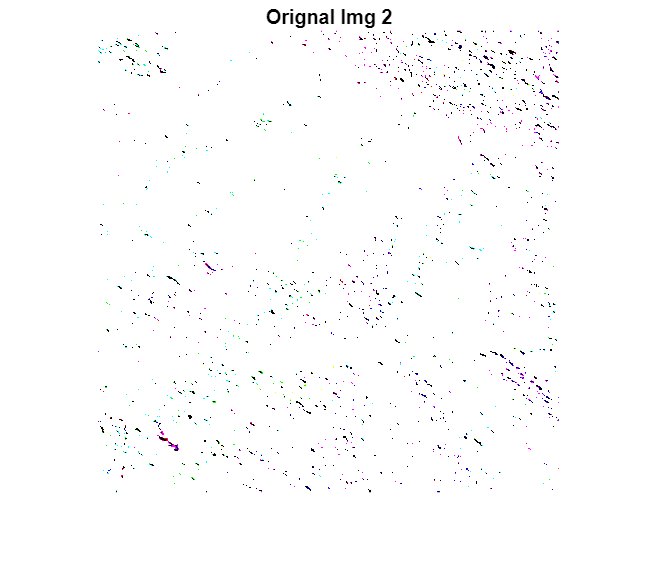

figure;
imshow(img_2);
title('Orignal Img 2');

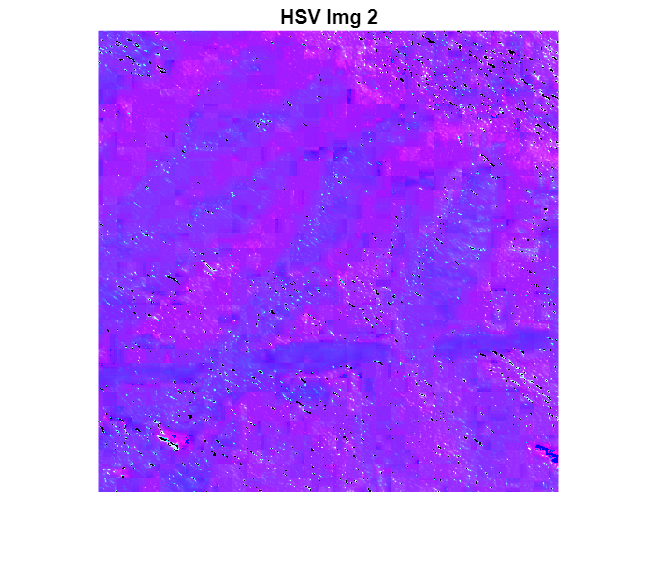

figure;
imshow(img_2_hsv);
title('HSV Img 2');

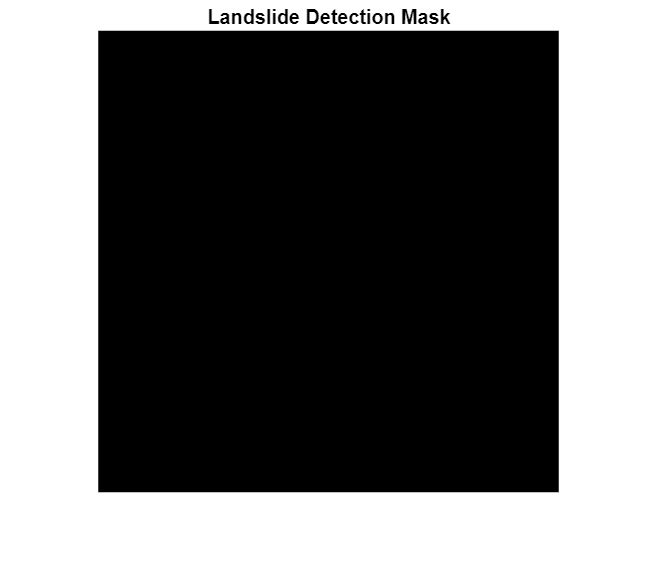

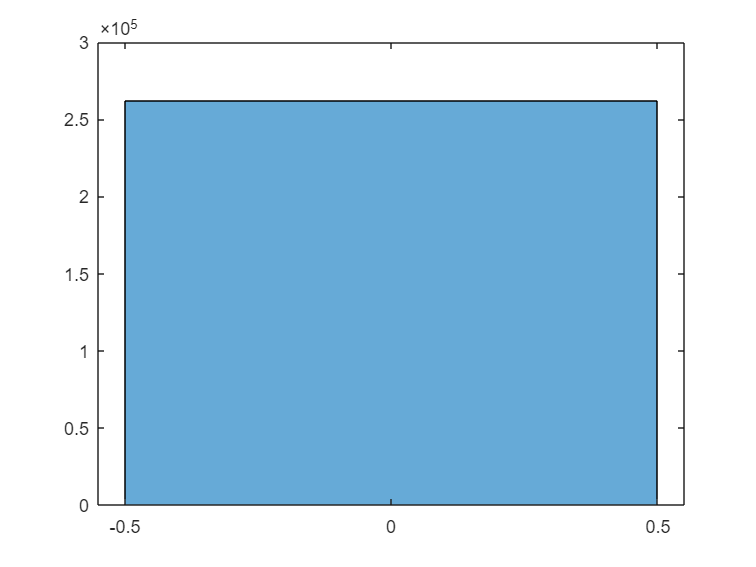

figure;
imshow(landside_mask);
title('Landslide Detection Mask');

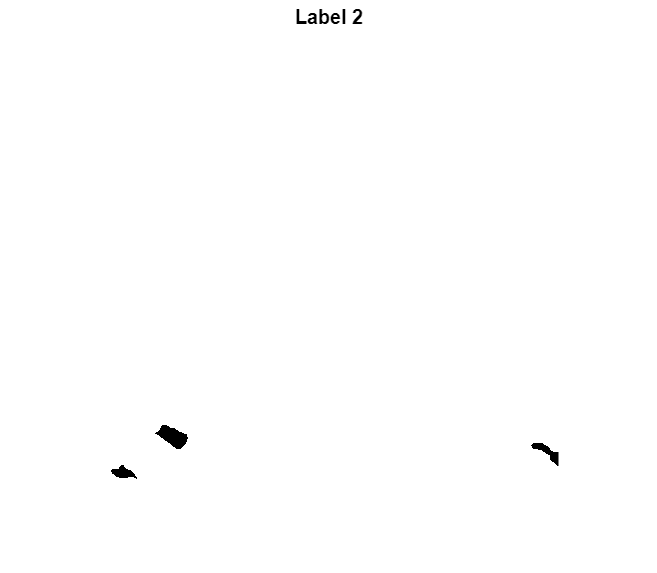

clear all
% IDENTIFY PATCHES
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";

% Select image
img_2 = double(imread(img_directory + 'Hokkaido0002.tif'));
label_2 = double(imread(label_directory + 'Hokkaido0002.tif'));

% (1) Init binary mask (2) Slide 10x10 window across image (3) Check if >=3 pixs in window match any landslide masks
% (4) If true set entire window in mask to 1

% Transform into HSV format
img_2_hsv = rgb2hsv(img_2);

% Lanslide masks (Conditions)
landslide_mask_blue = img_2_hsv(:,:,1) < 0.05 & img_2_hsv(:,:,2) < 0.2 & ...
                      img_2_hsv(:,:,3) > 0.6 & img_2_hsv(:,:,3) < 0.75;
landslide_mask_green = img_2_hsv(:,:,1) > 0.65 & img_2_hsv(:,:,1) < 0.8 & ...
                       img_2_hsv(:,:,2) > 0.9 & img_2_hsv(:,:,3) < 0.22;
landslide_mask_black = img_2_hsv(:,:,1) < 0.01 & img_2_hsv(:,:,2) < 0.01 & ...
                       img_2_hsv(:,:,3) < 0.1;
landslide_mask_purple = img_2_hsv(:,:,1) > 0.75 & img_2_hsv(:,:,1) < 0.95 & ...
                        img_2_hsv(:,:,2) < 0.09 & img_2_hsv(:,:,3) > 0.65 & ...
                        img_2_hsv(:,:,3) < 0.8;
landslide_mask_green2 = img_2_hsv(:,:,1) < 0.05 & img_2_hsv(:,:,2) > 0.95 & ...
                        img_2_hsv(:,:,3) < 0.15;
landslide_mask_green3 = img_2_hsv(:,:,1) < 0.05 & img_2_hsv(:,:,2) > 0.2 & ...
                        img_2_hsv(:,:,2) < 0.6 & img_2_hsv(:,:,3) > 0.35 & ...
                        img_2_hsv(:,:,3) < 0.65;

% Init binary mask
landslide_mask = zeros(512, 512);

% Define sliding window size
window_size = 25;
threshold = 50; % At least 3 pixels must match

% Iterate through the image with 10x10 window (Slide 10x10 window across image)
for row = 1:window_size:512-window_size+1
    for col = 1:window_size:512-window_size+1
        % Extract 10x10 window from each mask
        % Check how many pixels match any landslide mask (3) Check if >=3 pixs in window match any masks
        match_pixs = sum(...
            landslide_mask_blue(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_black(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_purple(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green2(row:row+window_size-1, col:col+window_size-1) | ...
            landslide_mask_green3(row:row+window_size-1, col:col+window_size-1), 'all');
        
        % If >=3 pixes match, mark entire 10x10 region as 1
        if match_pixs >= threshold
            landslide_mask(row:row+window_size-1, col:col+window_size-1) = 1;
        end
    end
end

% Display results
figure; imshow(label_2); title('Label 2');

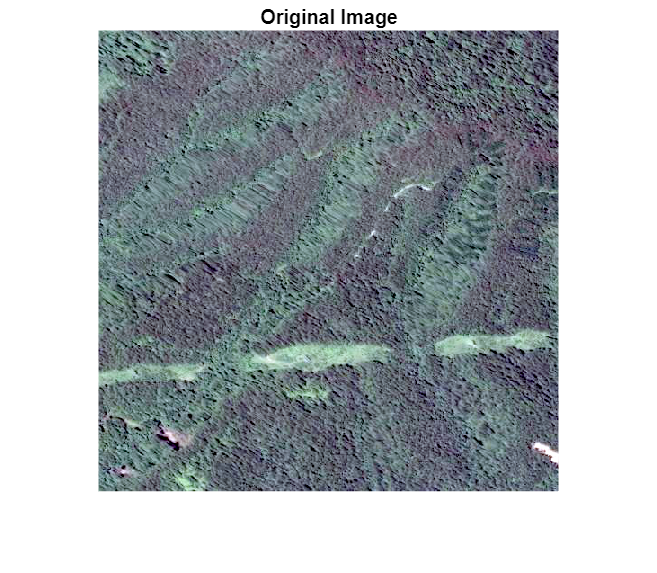

figure; imshow(img_2 / 255); title('Original Image');

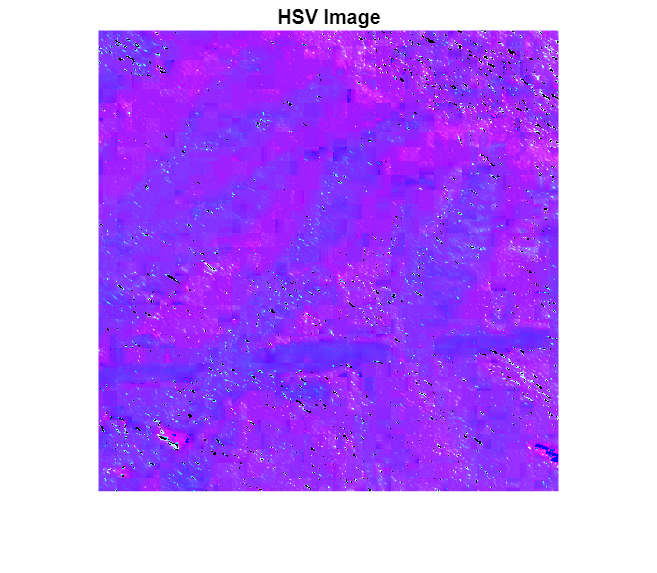

figure; imshow(img_2_hsv); title('HSV Image');

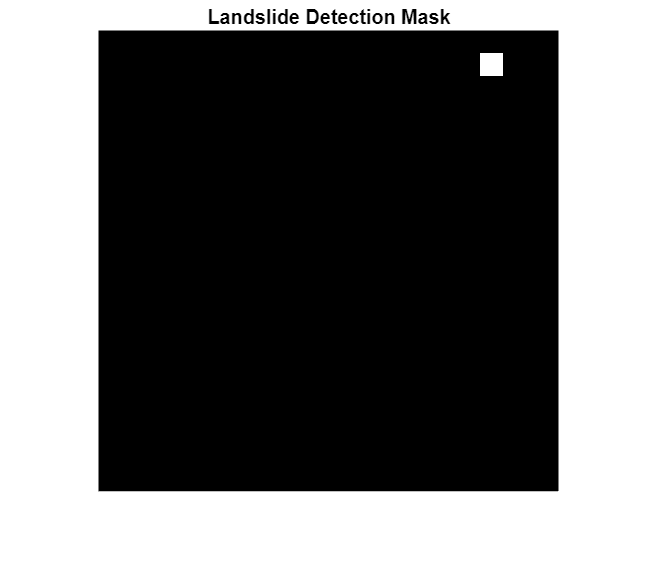

figure; imshow(landslide_mask); title('Landslide Detection Mask');